clear; clc; close;
caseName = "DMD_combustorDataPressure";


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   INSTRUCTIONS:
%     run this code after first reading the data using analyze_spectrum.mlx
%     then run this code from the section titles graphs to the end
%     this code is the good one that I belive works the best
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%if having gtrouble reading complex values try using
% fid = fopen(caseName + "_ContTimeEigVals", 'rt');
% contTimeEigVals = cell2mat(textscan(fid,'%*1c (%f)',"MultipleDelimsAsOne",true));
% fclose(fid);

%if other analysis program has run and gereated the apropriate file
%load(caseName + "_ContTimeEigVals.mat");

contTimeEigVals = str2num(cell2mat(importdata(caseName + "_ContTimeEigVals",','))); % read data from file as charater array segmented by ',' put it into a matrix

Brace indexing is not supported for variables of this type.

Error in cell2mat (line 42)
cellclass = class(c{1});

initialState = str2num(cell2mat(importdata(caseName + "_initialState",','))); % read data from file as charater array segmented by ',' put it into a matrix
b = str2num(cell2mat(importdata(caseName + "_initialAmplitudes",',')));

whos

initialState = initialState(1:end-1); % resize to match length of contTimeEigVals
b = b(1:end-1); % resize to match length of contTimeEigVals

## Graphs

psdData = [(abs(imag(contTimeEigVals(:)/2/pi))),abs(b(:)./abs(contTimeEigVals(:)))];

[max,maxIndex] = max(psdData(:,2))

max = 6.2886e+06

maxIndex = 3782

freqMax = psdData(maxIndex,1)

freqMax = 0

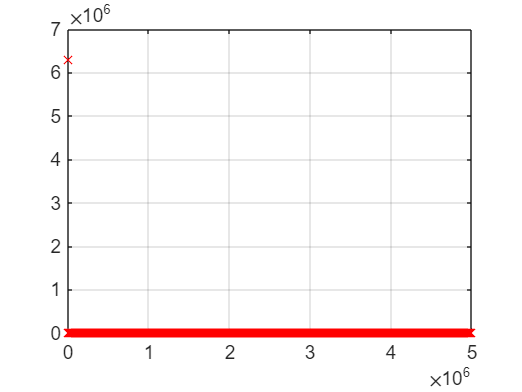


plot(psdData(:,1),psdData(:,2),'rx'); grid on;

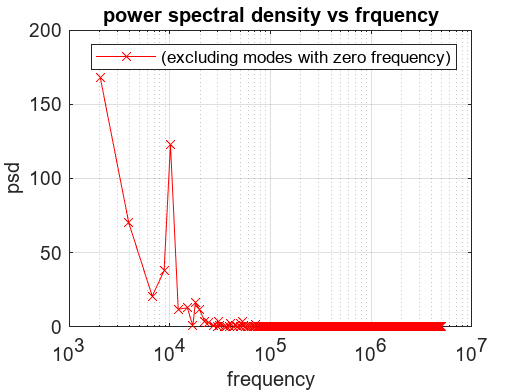

% semilogx(psdData(:,1),psdData(:,2),'rx'); grid on; %same as latter but
% without the lines that look nice

psdDataSorted =sortrows(psdData,1); % sort each column
% scatter(psdDataSorted(:,1),psdDataSorted(:,2),'rx'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency");
% plot(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency");
figure(1) = semilogx(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency"); legend("(excluding modes with zero frequency)"); % exclues modes with zero frequency
savefig("figure_"+caseName+"_psd_"+"noZeroFreqs"+".fig"); saveas(figure(1),"figure_"+caseName+"_psd_"+"noZeroFreqs"+".jpg");

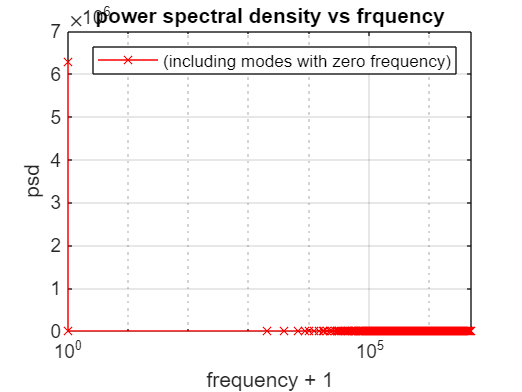

figure(2) = semilogx(psdDataSorted(:,1)+1,psdDataSorted(:,2),'r-x'); grid on; title("power spectral density vs frquency"); ylabel("psd"); xlabel("frequency + 1"); legend("(including modes with zero frequency)"); % includes the modes with zero frequency by offesting frequency by one
savefig("figure_"+caseName+"_psd_"+"withZeroFreqs"+".fig"); saveas(figure(2),"figure_"+caseName+"_psd_"+"withZeroFreqs"+".jpg");

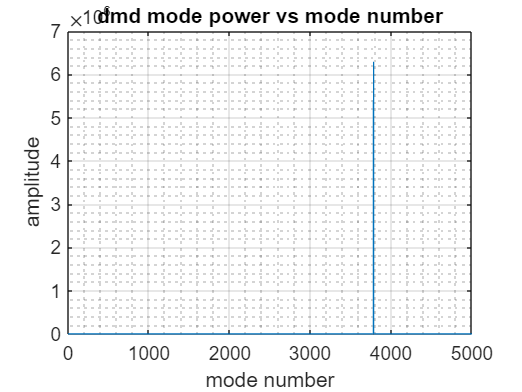




%usful for finding modes and debug

%mode power (scaled for grow/decay modes)
figure(3) = plot(abs(b./contTimeEigVals));grid on; grid minor;
title("dmd mode power vs mode number"); xlabel("mode number"); ylabel("amplitude");
savefig("figure"+caseName+"_psd vs mode number"+".fig"); saveas(figure(3),"figure"+caseName+"_psd vs mode numbe"+".jpg");

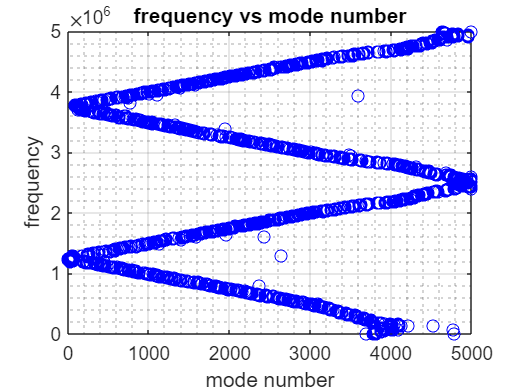


figure(4) = plot((abs(imag(contTimeEigVals/2/pi))),'bo'); grid on; grid minor;
title("frequency vs mode number"); ylabel("frequency"); xlabel("mode number");
savefig("figure"+caseName+" frequency vs mode number"+".fig"); saveas(figure(4),"figure"+caseName+" frequency vs mode number"+".jpg");

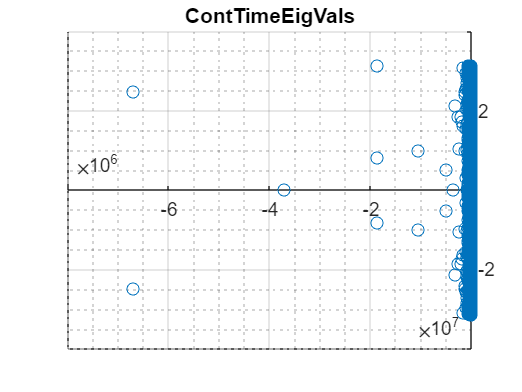


figure(5) = scatter(real(contTimeEigVals),imag(contTimeEigVals));grid on; grid minor;
title("ContTimeEigVals");
ax = gca; ax.YAxisLocation = 'origin'; ax.XAxisLocation = 'origin';
savefig("figure"+caseName+"_dmdsectrum"+".fig");saveas(figure(5),"figure"+caseName+"_dmdsectrum"+".jpg");


%fun but not super helpful
%loglog(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on; % does not include zero frequency
%loglog(psdDataSorted(:,1)+1,psdDataSorted(:,2),'r-x'); grid on; % includes zero frquency

%this is nice as is connects points in desending oder but is unforutnatly not exactly what i want
% psdDataSorted =sortrows(psdData,2); % sort each column
% scatter(psdDataSorted(:,1),psdDataSorted(:,2),'rx'); grid on;
% plot(psdDataSorted(:,1),psdDataSorted(:,2),'r-x'); grid on;